# Initializing

% Initializing path of HDF5 file
clear all;
rootpath= initialize_root_path; 
fileNameStr = [rootpath,'energy-height-conversion/PFISR_Energy_Spectra/Data/DataFile_2008_1.h5'];

% Initializing GeoData class
% initialize_geodata([rootpath,'energy-height-conversion\GeoDataMATLAB\']);


## Extracting data

pfisrGD = GeoData(@readMadhdf5,fileNameStr,{'popl'});

PFISR data



% Change the log electron density to linear density
antilog = @(ex,base)(base.^ex);
pfisrGD.changedata('popl','ne',antilog,{10});
% pfisrGD.interpolate(pfisrGD.dataloc,'Cartesian','natural');

% Removing NANs
data.electronDensity = pfisrGD.data.ne;
data.time = unix_to_matlab_time(pfisrGD.times(:,1));
nBeams=26;
nData = length(data.electronDensity(:,1));
for itime=1:1:length(data.time)
    for iBeam = 1:1:26
        data.electronDensity(iBeam:nBeams:nData,itime)...
            = interp_nans(data.electronDensity(iBeam:nBeams:nData,itime));
    end
end
pfisrGD.data.ne = data.electronDensity;

## Converting coordinates to Geodetic

% [cartCoords(:,1),cartCoords(:,2),cartCoords(:,3)] = sph2cart(degtorad(pfisrGD.dataloc(:,2)),degtorad(pfisrGD.dataloc(:,3)),pfisrGD.dataloc(:,1));
az=pfisrGD.dataloc(:,2);
elev=pfisrGD.dataloc(:,3);
slant=pfisrGD.dataloc(:,1);
[yNorth, xEast, zDown] = aer2ned(az,elev,slant);
%figure; plot(xEast(1:26),yNorth(1:26),'o');
lat0 = 65.126;
lon0 = -147.47;
height = 0.689;
[geodeticCoords(:,1),geodeticCoords(:,2),geodeticCoords(:,3)] = ned2geodetic(yNorth,xEast,zDown,lat0,lon0,height,wgs84Ellipsoid('km'));

## Plot 2D map

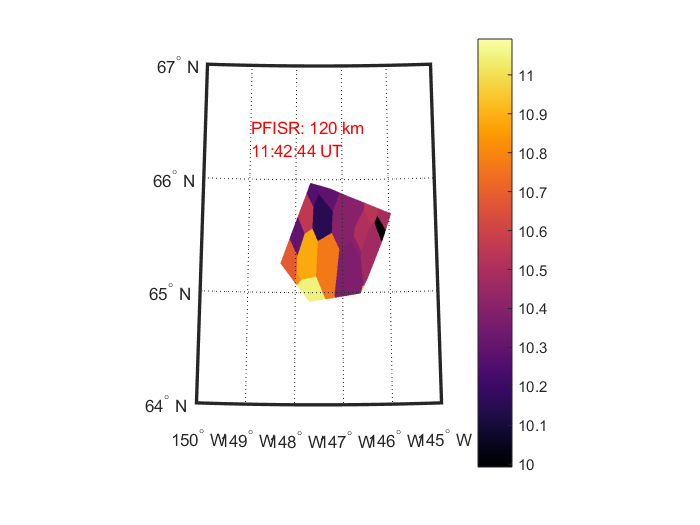

thisTime = '26-Mar-2008 11:43';
[timeNo] = find_time(data.time, thisTime);
figure;
plot_2D_density_slice_geodetic...
    (data, geodeticCoords, timeNo, 120, true);
colormap(inferno);
colorbar;

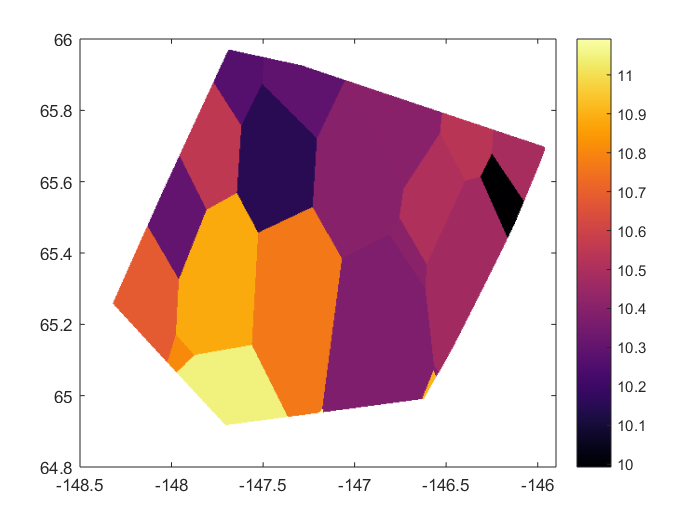

figure;
plot_2D_density_slice_geodetic...
    (data, geodeticCoords, timeNo, 120, false, [64.8,66], [-148.5,-145.9]);
colormap(inferno);
colorbar;

## Magnetic field aligned coordinates

minTimeStr = '26-Mar-2008 10:42';
maxTimeStr = '26-Mar-2008 10:44';
thisAltitude = 60; % in Km
magBeamNo = 1;
pfisrGDmag = copy(pfisrGD);
pfisrGDmag.data.ne = data.electronDensity;
[ pfisrGDmag, magcoords, atTime, atAltitude] = geodata_magnetic_field_interpolation...
    ( pfisrGDmag, minTimeStr, maxTimeStr, thisAltitude, magBeamNo);

Interpolating parameter ne, 1 of 1
	Interpolating time 1 of 2
	Interpolating time 2 of 2


## Plotting magnetically interpolated density

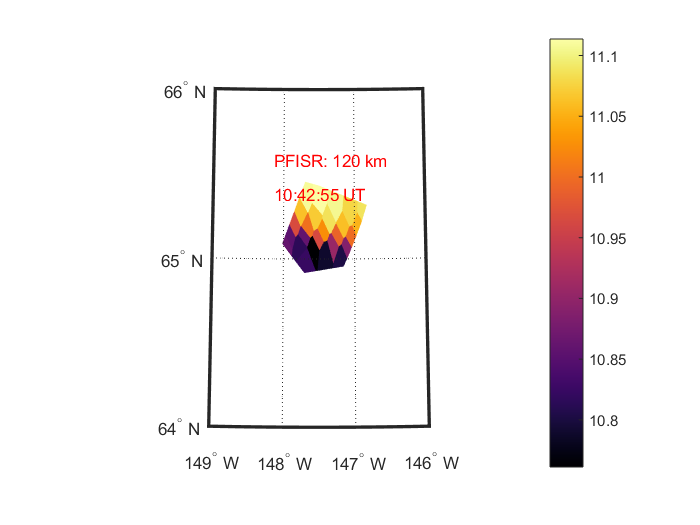

[geodeticMagCoords(:,1),geodeticMagCoords(:,2),geodeticMagCoords(:,3)] = ned2geodetic(magcoords(:,2),magcoords(:,1),-magcoords(:,3),lat0,lon0,height,wgs84Ellipsoid('km'));
dataMag.electronDensity=pfisrGDmag.data.ne;
dataMag.time = unix_to_matlab_time(pfisrGDmag.times(:,1));
thisTime = '26-Mar-2008 10:43';
[timeNo] = find_time(dataMag.time, thisTime);

figure;
plot_2D_density_slice_geodetic...
    (dataMag, geodeticMagCoords, timeNo, 120, true);
colormap(inferno);
colorbar;

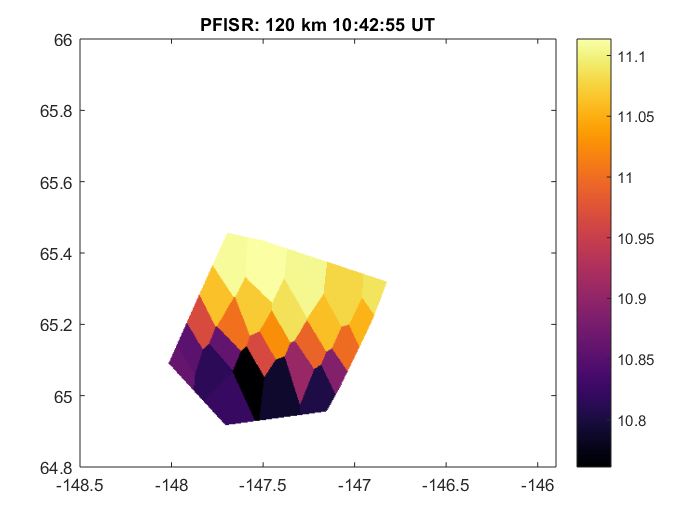

figure;
plot_2D_density_slice_geodetic...
    (dataMag, geodeticMagCoords, timeNo, 120, false, [64.8,66], [-148.5,-145.9]);
colormap(inferno);
colorbar;

## Calculating conductivity

for itime=1:1:length(dataMag.time)
    for iBeam=1:1:nBeams
        avgLat      = mean(geodeticMagCoords(iBeam:nBeams:nData,1));
        avgLon      = mean(geodeticMagCoords(iBeam:nBeams:nData,2));
        altitude    = geodeticMagCoords(iBeam:nBeams:nData,3);
        if iBeam<2
            [altitudeNo] = find_altitude( altitude, 80);
        end
        altStart=iBeam+nBeams*(altitudeNo-1);
        conductanceLat = geodeticMagCoords(altStart:nBeams:nData,1);
        conductanceLon = geodeticMagCoords(altStart:nBeams:nData,2);
        conductanceAlt = geodeticMagCoords(altStart:nBeams:nData,3);
    
        conductanceData = get_conductivity_v1(conductanceAlt,...
            dataMag.electronDensity(altStart:nBeams:nData),avgLat,avgLon,dataMag.time(itime));
        nBeamConductance = length(conductanceAlt);
        dataMag.sigma_H(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,itime) = conductanceData.sigma_H;
        dataMag.sigma_P(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,itime) = conductanceData.sigma_P;
        dataMag.conductanceCoords(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,1,itime) = conductanceLat;
        dataMag.conductanceCoords(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,2,itime) = conductanceLon;
        dataMag.conductanceCoords(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,3,itime) = conductanceAlt;
        iBeam
        mod(length(dataMag.conductanceCoords(:,3)),218)
        size(conductanceAlt)
        if (sum(dataMag.conductanceCoords(:,3,itime)<70))>0
            iBeam
            return
        end
    end
end

iBeam = 1

ans = 0

ans =    218     1


iBeam = 2

ans = 0

ans =    218     1


iBeam = 3

ans = 0

ans =    218     1


iBeam = 4

ans = 0

ans =    218     1


iBeam = 5

ans = 0

ans =    218     1


iBeam = 6

ans = 0

ans =    218     1


iBeam = 7

ans = 0

ans =    218     1


iBeam = 8

ans = 0

ans =    218     1


iBeam = 9

ans = 0

ans =    218     1


iBeam = 10

ans = 0

ans =    218     1


iBeam = 11

ans = 0

ans =    218     1


iBeam = 12

ans = 0

ans =    218     1


iBeam = 13

ans = 0

ans =    218     1


iBeam = 14

ans = 0

ans =    218     1


iBeam = 15

ans = 0

ans =    218     1


iBeam = 16

ans = 0

ans =    218     1


iBeam = 17

ans = 0

ans =    218     1


iBeam = 18

ans = 0

ans =    218     1


iBeam = 19

ans = 0

ans =    218     1


iBeam = 20

ans = 0

ans =    218     1


iBeam = 21

ans = 0

ans =    218     1


iBeam = 22

ans = 0

ans =    218     1


iBeam = 23

ans = 0

ans =    218     1


iBeam = 24

ans = 0

ans =    218     1


iBeam = 25

ans = 0

ans =    218     1


iBeam = 26

ans = 0

ans =    218     1


iBeam = 1

ans = 0

ans =    218     1


iBeam = 1

## Plotting conductivity

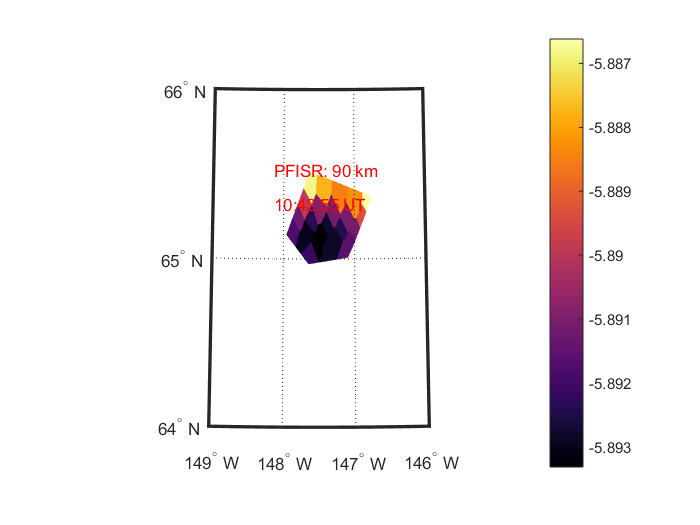

thisTime = '26-Mar-2008 10:43';
[timeNo] = find_time(dataMag.time, thisTime);

figure;
plot_2D_conductivity_slice_geodetic...
    (dataMag, dataMag.conductanceCoords, timeNo, 90, 'H', true);
colormap(inferno);
colorbar;

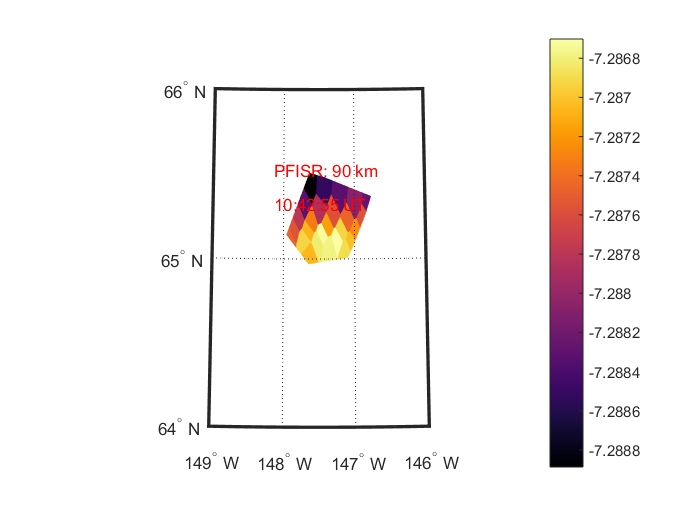

figure;
plot_2D_conductivity_slice_geodetic...
    (dataMag, dataMag.conductanceCoords, timeNo, 90, 'P', true);
colormap(inferno);
colorbar;